%==========================================================================
% Author:    Naghmeh Akhavan (N. Akhavan)
% Affil.:    University of Michigan
% Contact:   nakhavan@umich.edu
%
% Goal:
%   Quantify how the probability of entering a "sequential" REM cycle depends
%   on REM propensity in Humans, after applying a strict long-wake exclusion.
%
% Scientific definitions used here:
%   • Long-wake DROP (per REM cycle):
%       Drop a cycle if the StageDetails table contains ANY single Wake block
%       with duration ≥ WAKE_BREAK_MIN minutes within the Inter-REM interval.
%       (Wake blocks are identified by WAKE_LABEL in StageDetails.)
%
%   • Propensity (hazard-like quantity):
%       Let F(t) be the CDF of NREM duration |N| (in seconds) since the previous
%       REM, estimated from a 2-component Gaussian mixture model (GMM) fit to
%       z = log(|N|). For a horizon Δ = DELTA_SEC:
%
%           P(t,Δ) = [F(t+Δ) − F(t)] / [1 − F(t)].
%
%   • Increasing-zone window (precomputed):
%       Use a fixed NREM window [tMin_s, tMax1_s] that was previously estimated
%       as "global minimum of P(t,Δ)" → "first local maximum after that minimum".
%       Only cycles whose NREM duration N_s lies in this window are analyzed.
%
%   • Sequential REMpost:
%       A REMpost is labeled "sequential" if the NEXT Inter-REM duration
%       (IREM_next) for the same subject is ≤ SEQ_THRESH_MIN minutes.
%
% What this script produces:
%   • A single bar plot: sequential occurrence rate vs propensity (increasing zone).
%     Occurrence rate in each propensity bin = mean(Seq) = fraction sequential.
%   • Console diagnostics: kept/dropped counts, in-window counts, bin counts,
%     and overall sequential rate.
%
% Inputs (filesystem):
%   combinedFolder/
%     Combined_BigResultTable.mat        (cycle-level summary table R)
%     Combined_BigStageDetailsTable.mat  (stage-by-stage table D; used for LW DROP
%                                        and for establishing within-subject order)
%
% Outputs:
%   • Figure (not saved by default): bar chart of sequential rate vs propensity
%
% Assumptions / Notes:
%   • This is "toolbox-free" in the sense that the GMM fit uses a custom EM and
%     quantiles are computed by quantile_nontb (no Statistics Toolbox).
%   • The increasing-zone endpoints are hard-coded; if you recompute propensity
%     with different Δ or filtering, these values should be updated accordingly.
%
% Last updated: 2026-01-19
%==========================================================================
clear; clc;


## Paths & knobs

combinedFolder   = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';
matR = fullfile(combinedFolder, 'Combined_BigResultTable.mat');
matD = fullfile(combinedFolder, 'Combined_BigStageDetailsTable.mat');

assert(isfile(matR), 'Missing %s.', matR);
assert(isfile(matD), 'Missing %s.', matD);

% Stage coding
WAKE_LABEL      = 5;   % change if your Wake code differs


## Long-wake DROP threshold + Setting

WAKE_BREAK_MIN  = 2;
WAKE_BREAK_SEC  = WAKE_BREAK_MIN*60;

% Propensity horizon Δt
DELTA_SEC       = 30;

% PRECOMPUTED increasing-zone window
tMin_s          = 1373;   % global min
tMax1_s         = 6693;   % first local max

% "Sequential" threshold: next IREM ≤ this
SEQ_THRESH_MIN  = 2;
SEQ_THRESH_SEC  = SEQ_THRESH_MIN*60;

% Binning for the rate panel
NBINS_PROP      = 10;


## Load & normalize

S1 = load(matR);  R = S1.Combined_BigResultTable;
S2 = load(matD);  D = S2.Combined_BigStageDetailsTable;

toStr = @(x) string(x);
% normalize types in R: Stage details
R.Subject_Index   = toStr(R.Subject_Index);
R.REM_Cycle_Index = toStr(R.REM_Cycle_Index);
if ismember('Species', string(R.Properties.VariableNames))
    R.Species = toStr(R.Species);
end

% normalize types in D: Stage details
D.REM_Cycle_Index = toStr(D.REM_Cycle_Index);
D.Stage    = double(D.Stage);
D.Duration = double(D.Duration);

% Ensure numeric columns exists in R
needR = ["REMpre","NREM","Wake","Movement","IREM","REMpost"];
for v = needR
    if ~ismember(v, string(R.Properties.VariableNames)), R.(v) = NaN(height(R),1); end
    R.(v) = double(R.(v));
end
if all(isnan(R.IREM)) && all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
    R.IREM = R.NREM + R.Wake + R.Movement;
end

% Keep humans if available (sanity check)
if ismember('Species', string(R.Properties.VariableNames))
    R = R(R.Species=="Human" | R.Species=="", :);
end


## Long-wake DROP per cycle

D.ord = (1:height(D))';
D = sortrows(D, {'REM_Cycle_Index','ord'});

[Gd, keys] = findgroups(D.REM_Cycle_Index);
hasLongWake = false(numel(keys),1);
for gi = 1:numel(keys)
    idx = find(Gd==gi);
    st  = D.Stage(idx);
    du  = D.Duration(idx);
    if any(st==WAKE_LABEL & du>=WAKE_BREAK_SEC)
        hasLongWake(gi) = true;
    end
end

FlagLW = table(keys, hasLongWake, 'VariableNames',{'REM_Cycle_Index','HasLongWake'});
R = outerjoin(R, FlagLW, 'Keys','REM_Cycle_Index', 'MergeKeys',true, 'Type','left');

Rkeep = R(R.HasLongWake~=1, :);
fprintf('Long-wake DROP (>= %d min): kept %d of %d cycles.\n', WAKE_BREAK_MIN, height(Rkeep), height(R));

Long-wake DROP (>= 2 min): kept 3994 of 5022 cycles.


## Build arrays: one set for GMM, one set for sequential labeling

% For GMM fit: ALL kept cycles (independent of REMpost)
N_all = Rkeep.NREM;
valid_all = isfinite(N_all) & (N_all>0);
N_all = N_all(valid_all);

% For sequential analysis: require NREM & REMpost present
N_s        = Rkeep.NREM;
REMpost_s  = Rkeep.REMpost;
valid_seq  = isfinite(N_s) & N_s>0 & isfinite(REMpost_s) & REMpost_s>0;

N_s        = N_s(valid_seq);
REMpost_s  = REMpost_s(valid_seq);
Subj_v     = Rkeep.Subject_Index(valid_seq);
CyID_v     = Rkeep.REM_Cycle_Index(valid_seq);
IREM_v     = Rkeep.IREM(valid_seq);
REMpre_v   = Rkeep.REMpre(valid_seq);

fprintf('Valid cycles for GMM fit: %d\n', numel(N_all));

Valid cycles for GMM fit: 3397


fprintf('Valid cycles for sequential analysis: %d\n', numel(N_s));

Valid cycles for sequential analysis: 3202



if isempty(N_all) || isempty(N_s)
    error('Insufficient data after long-wake filtering.');
end


## Fit a lumped 2-component GMM to log(NREM)

z_all = log(N_all(:)); z_all = z_all(isfinite(z_all));
[w, mu, sd] = fit_gmm_1d(z_all, 2, struct('nStarts',30,'maxIter',200,'tol',1e-6, ...
                                          'trimFrac',0.01,'sdMin',0.08,'sdMax',3.0, ...
                                          'clipQuantiles',[0.5 99.5]));
Phi = @(u) 0.5*(1+erf(u./sqrt(2)));
gmm_cdf_seconds = @(tt) arrayfun(@(x) sum(w .* Phi((log(max(x,eps))-mu)./sd)), tt);


## Compute propensity at each cycle's REMpost onset

P_onset = ( gmm_cdf_seconds(N_s + DELTA_SEC) - gmm_cdf_seconds(N_s) ) ...
          ./ max(1 - gmm_cdf_seconds(N_s), eps);

% Increasing-zone mask (PRECOMPUTED)
inWindow = (N_s >= tMin_s) & (N_s <= tMax1_s);
fprintf('In increasing zone [%d,%d] s: %d (%.1f%%)\n', ...
        tMin_s, tMax1_s, sum(inWindow), 100*mean(inWindow));

In increasing zone [1373,6693] s: 786 (24.5%)


## Determine "next IREM" per subject, using cycle order from StageDetails

% chronological order for cycles from stage table
[Gc, kcy] = findgroups(D.REM_Cycle_Index);
firstOrd  = splitapply(@min, D.ord, Gc);
OrderTbl  = table(kcy, firstOrd, 'VariableNames',{'REM_Cycle_Index','FirstOrd'});

% assemble table for valid cycles
T = table(Subj_v, CyID_v, N_s, REMpost_s, P_onset, IREM_v, REMpre_v, ...
          'VariableNames',{'Subj','Cycle','N_s','REMpost_s','P_onset','IREM','REMpre'});
T = outerjoin(T, OrderTbl, 'LeftKeys','Cycle', 'RightKeys','REM_Cycle_Index', 'Type','left');

% next IREM per subject (last cycle has NaN)
T.IREM_next = NaN(height(T),1);
[Gsubj, subjK] = findgroups(T.Subj);
for gi = 1:numel(subjK)
    idx = find(Gsubj==gi & isfinite(T.FirstOrd));
    if isempty(idx), continue; end
    [~, ord] = sort(T.FirstOrd(idx), 'ascend');
    ii = idx(ord);
    if numel(ii) >= 2
        T.IREM_next(ii(1:end-1)) = T.IREM(ii(2:end));
    end
end


## Sequential label and final restriction

T.Seq = double(T.IREM_next <= SEQ_THRESH_SEC);
T.Seq(~isfinite(T.IREM_next)) = NaN;

% restrict to increasing zone & valid label
mKeep = inWindow & isfinite(T.Seq);
xSeq  = T.P_onset(mKeep);
ySeq  = T.Seq(mKeep);

fprintf('Usable cycles in increasing zone with Seq label: %d\n', numel(xSeq));

Usable cycles in increasing zone with Seq label: 636


if isempty(xSeq)
    error('No usable data in increasing zone — check thresholds/window.');
end


## Occurrence rate vs propensity (bars only)

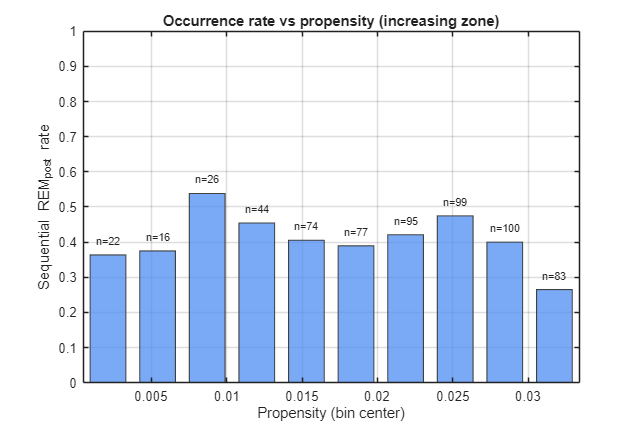

figure('Color','w','Position',[130 140 640 430], ...
    'Name', sprintf('Human: Occurrence rate vs Propensity (LW \\ge %g min)', WAKE_BREAK_MIN));

edges   = linspace(min(xSeq), max(xSeq), NBINS_PROP+1);
[~,~,bid] = histcounts(xSeq, edges);
centers = (edges(1:end-1)+edges(2:end))/2;

rate = nan(1, NBINS_PROP); nbin = zeros(1, NBINS_PROP);
for b = 1:NBINS_PROP
    m = (bid==b);
    nbin(b) = sum(m);
    if nbin(b)>0, rate(b) = mean(ySeq(m),'omitnan'); end
end

barWidth = 0.72;
h = bar(centers, rate, barWidth, ...
    'FaceAlpha', 0.75, ...
    'FaceColor', [0.30 0.55 0.95], ...
    'EdgeColor', [0.25 0.25 0.25], 'LineWidth', 0.8);
hold on; grid on; box on;
xlabel('Propensity (bin center)');
ylabel('Sequential REM_{post} rate');
title('Occurrence rate vs propensity (increasing zone)');
ylim([0 1]); xlim([edges(1) edges(end)]);
uistack(h,'top');

% annotate bin counts
for b = 1:NBINS_PROP
    if nbin(b)>0
        text(centers(b), min(rate(b)+0.04,0.98), sprintf('n=%d', nbin(b)), ...
            'HorizontalAlignment','center', 'FontSize', 8);
    end
end


fprintf('Overall sequential rate (in-zone): %.3f\n', mean(ySeq,'omitnan'));

Overall sequential rate (in-zone): 0.404


## Functions (GMM + EM + quantile)

function [w, mu, sd, info] = fit_gmm_1d(x, K, opts)
    x = x(:); x = x(isfinite(x));
    if nargin<3, opts = struct; end
    g = @(f,def) (isfield(opts,f)&&~isempty(opts.(f))).*opts.(f) + ...
                 (~isfield(opts,f)||isempty(opts.(f))).*def;
    nStarts  = g('nStarts',30);
    maxIter  = g('maxIter',200);
    tol      = g('tol',1e-6);
    trimFrac = g('trimFrac',0.01);
    sdMin    = g('sdMin',0.08);
    sdMax    = g('sdMax',3.0);
    cq       = g('clipQuantiles',[0.5 99.5]);

    qlo = quantile_nontb(x, cq(1)/100);
    qhi = quantile_nontb(x, cq(2)/100);
    x   = x(x>=qlo & x<=qhi); 
    log2pi = log(2*pi); 

    bestLL = -inf; best = [];
    for s = 1:nStarts
        q20 = quantile_nontb(x,0.20); q80 = quantile_nontb(x,0.80);
        mu0 = linspace(q20,q80,K) + 0.05*randn(1,K);
        sd0 = max(sdMin, 0.3*std(x))*ones(1,K);
        w0  = ones(1,K)/K;
        [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
        if LL(end) > bestLL, best = {w1,mu1,sd1,LL}; bestLL = LL(end); end
    end
    [w, mu, sd, LL] = best{:}; 
    info = struct('loglik',LL,'nStarts',nStarts,'n',numel(x));
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
    n = numel(x); K = numel(w); LL = zeros(maxIter,1); trimN = floor(trimFrac*n);
    for it = 1:maxIter
        logp = zeros(n,K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); p = exp(logp - m); s = sum(p,2);
        gamma = p ./ max(s,eps);

        if trimN>0
            [~,idx] = sort(s, 'ascend'); keep = true(n,1); keep(idx(1:trimN)) = false;
        else
            keep = true(n,1);
        end
        Nk = sum(gamma(keep,:), 1); w = Nk ./ max(sum(Nk), eps);
        for k=1:K
            mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k), eps);
            v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k), eps);
            sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
        end

        logp = zeros(sum(keep),K); xk = x(keep);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m  = max(logp,[],2);
        LL(it) = sum(m + log(sum(exp(logp - m),2)));
        if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1))), LL = LL(1:it); break; end
    end
    LL = LL(1:it);
end

function q = quantile_nontb(x, probs)
    x = sort(x(:)); n = numel(x); q = zeros(size(probs));
    for k = 1:numel(probs)
        p = probs(k); if n==1, q(k) = x; continue; end
        idx = (n-1)*p + 1; i0 = floor(idx); i1 = ceil(idx);
        if i0==i1, q(k) = x(i0);
        else, w = idx-i0; q(k) = (1-w)*x(i0)+w*x(i1); end
    end
end
